# Lab 1 Playing with PID

The transfer function of plant is given as:


$$G\left(s\right)=\frac{e^{-0\ldotp 2\;s} }{s^2 +s}$$


s = tf('s');
G = 1/(s^2+s);
G.iodelay = 0.2;

Remark: note that this system contains a pure time delay. 

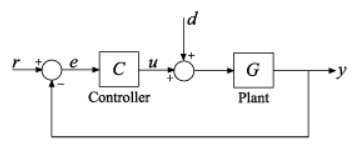

figure 1: feedback structure

We will compute the controller C and consider a negative unitary feedback (figure 1). We will analyse:

- The closed loop step response (r to y). Transfer functions  T=feedback(C*G,1)

- The  perturbation to output step response (d to y). Transfer function P=feedback(G,C)

- The Bode diagram

- The Nyquist diagram

- The sensitivity function. Transfer function S=feedback(1,C*G)

Hint 1: The Matlab Liv editor is nice for many things, except for plotting. For a better use of Bode plots (and other plots) you create external  figures from the command line or enforce external plots with command

>> set(gcf,'Visible','on');

Hint 2: we wil prefer the use of T1=feedback(C*G,1) instead of T2=C*G/(1+C*G). In T2 we have C*G in series with 1/(1+C*G) and Matlab does not cancel extra poles with corresponding zeros, consequently generates virtual non observable and/or non controllable poles...

## 1 Basic control

We first control the system with a pure proportional controler and find the achievable performances.

**Question 1:** what is the gain K1  and the crossover frequency wc if we want a phase margin of 60°?

% MODIFY

%bode(G)
%grid on
K1= 10^(-6.02/20)
%bode(K1*G)

%grid on

K1 = 0.5000


% 

Answer here

K1 = 0.5   wc = 0.458 rad/s

**Question 2**: what is gain K2  and the phase margin if we want a crossover frequency wc=1 rad/s?

% MODIFY

K2= 10^(3.02/20)

K2 = 1.4158

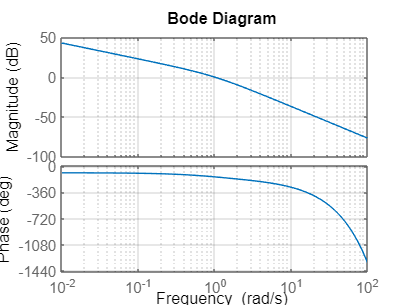

bode(K2*G)
grid on


% 

Answer here

K2 = 1.4158   phase margin = 33.5 deg

**Question 3**: compare the step response (r to y) and perturbation rejection (d to y) of both closed loop systems

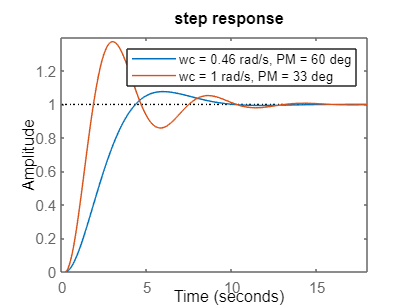

T1 = feedback(K1*G,1);
T2 = feedback(K2*G,1);
P1 = feedback(G,K1);
P2 = feedback(G,K2);
step(T1,T2); 
title('step response');
legend('wc = 0.46 rad/s, PM = 60 deg','wc = 1 rad/s, PM = 33 deg');

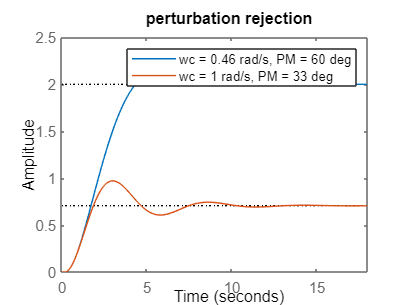

step(P1,P2); 
title('perturbation rejection');
legend('wc = 0.46 rad/s, PM = 60 deg','wc = 1 rad/s, PM = 33 deg');

Discussion here

K1 controller has a better step response due to minimal oscillation. However, K2 has a better perturbation rejection since it has a lower amplitude of perturbation.

**Question 4**: compare the closed loop systems in terms of time response, phase margin, overshoot, static perturbation rejection...

Discussion here

See the plots and compare.

**Question 5**: what is the limit value Klim that causes unstability? Answer the quesiton with the root locus diagram (rlocus Matlab function) and a Pade approximation for the delay (pade function)

The root locus cannot easily be plotted because of the time delay. Since this delay is small it can be correctly approximated by a linear transfer function with a first order Pade approximation.

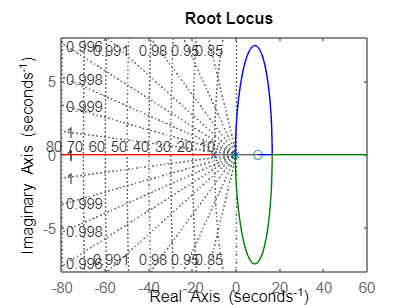

[num,den]=pade(0.2,1);
R=tf(num,den);
% MODIFY

rlocus(R*(1/(s^2+s)))
grid on

% 

Answer here

Klim = 5.3

## 2 Ziegler Nichols

This method allows to quickly obtain the parameters of a PID that "works in most cases". Although very old fashioned this method is still used in some industrial processes.

Step 1 : find the value Klim of the pure proportional controller that gives limit of closed loop unstability

% MODIFY

Klim= 5.2

T = feedback(Klim*R*(1/(s^2+s)),1);

Klim = 5.2000

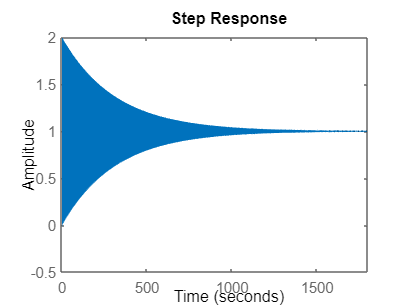

step(T)
Tlim = 3
% 

Step 2: The Ziegler Nichols of a PID are given by the formula below. (Other formulas for a P, PI, PD, see wikipedia)

Kp = 0.6*Klim;

Tlim = 3

Ki = 1.2*Klim/Tlim;
Kd = 0.075*Klim*Tlim;
Cz = Kp + Ki/s + Kd*s;

**Question 6**: compare the performance with the performance of the controller obtained in question 1

Tz = feedback(Cz*G,1); % Reference to output transfer function
Pz = feedback(G,Cz); % Perturbation to output transfer function
Sz = feedback(1,Cz*G); % Sensitivity function
% MODIFY

Q1_step = feedback(K1*G,1)
Q1_perturb = feedback(G,K1)
Q1_sensitivity = feedback(1,K1*G)
step(Tz,Q1_step)
grid on

Q1_step =
 
  A = 
         x1    x2
   x1    -1  -0.5
   x2     1     0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
        x1   x2
   y1    0  0.5
 
  D = 
       u1
   y1   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.2 
 
Continuous-time state-space model.



step(Pz,Q1_perturb)

Q1_perturb =
 
  A = 
         x1    x2
   x1    -1  -0.5
   x2     1     0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.2 
 
Continuous-time state-space model.



grid on

Q1_sensitivity =
 
  A = 
         x1    x2
   x1    -1  -0.5
   x2     1     0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
         x1    x2
   y1     0  -0.5
 
  D = 
       u1
   y1   1
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.2 
 
Continuous-time state-space model.



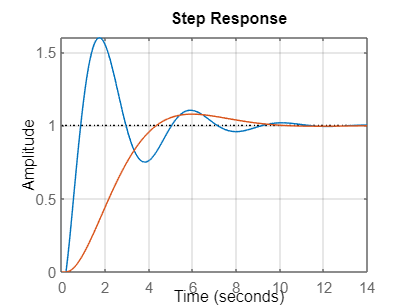

step(Sz,Q1_sensitivity)
grid on

% 

Discussion here

**Question 7**: What are the step response characteristics ?

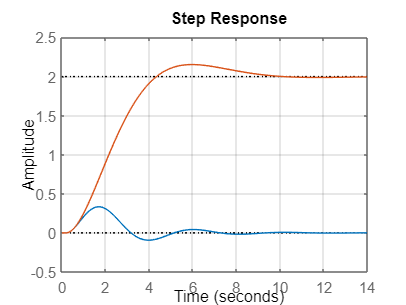

step(Tz);title('ZN step response');

step(Pz);title('ZN perturbation rejection');

Discussion here

**Question 8**: What is the phase margin? What is the crossover frequency?

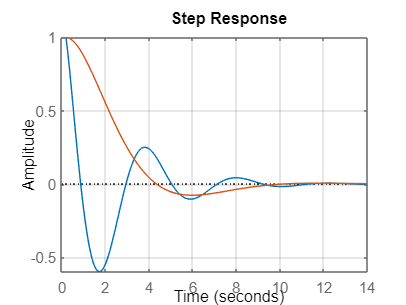

set(gcf,'Visible','on');

margin(Cz*G)
PM = 24 % deg
wc = 1.63; % rad/s

We can also compare the three controllers;

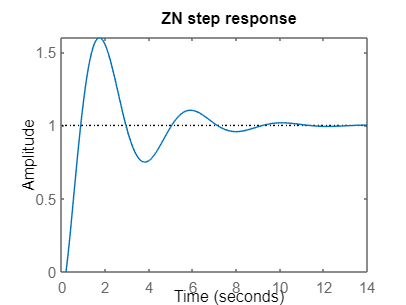

step(T1,T2,Tz);

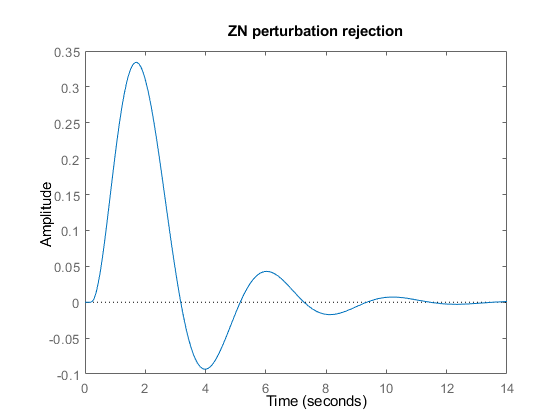

legend('wc = 0.46 rad/s, PM = 60 deg','wc = 1 rad/s, PM = 33 deg','ZN');
title('step response')
step(P1,P2,Pz);
legend('wc = 0.46 rad/s, PM = 60 deg','wc = 1 rad/s, PM = 33 deg','ZN');

title('perturbation rejection')

discussion here

## 3 Advanced design, pidtune

The required crossover frequency is wc=1 rad/s and the expected closed loop phase margin is 60°

wc = 1.5;

PM = 24

PM=60

### 3.1 Tuning a PID with pidtune

Have a look to the documentation of pidtune. pidtune performs an optimisation and tries to achieve the required performance goal (default for phase margin is 60°)

opts3 = pidtuneOptions('PhaseMargin',60)

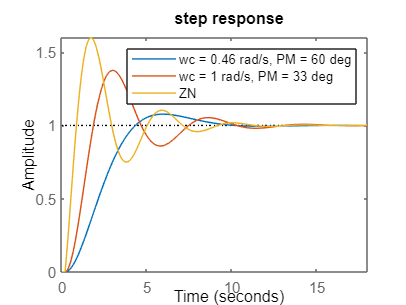

[C3,info] = pidtune(G,'PID',wc,opts3)
T3 = feedback(G*C3,1);

P3 = feedback(G,C3);

in the **variable** info we see that the optimizer succesfully achieved the required performance . It is not always the case... (Try more demanding crossover frequencies)

**Question 9**: compare the performance of this controller with the ones obtained before

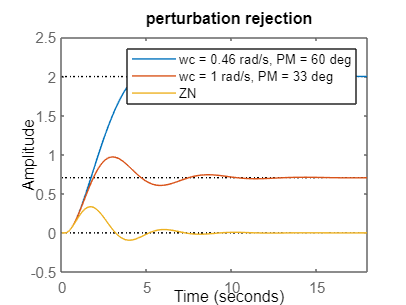

step(T1,T2,Tz,T3);
legend('wc = 0.46 rad/s, PM = 60 deg',...

    'wc = 1 rad/s, PM = 33 deg',...
    'ZN wc = 1.63 rad/s, PM = 24 deg',...
    'pidtune balanced wc = 1.5 rad/s, PM = 60 deg');
title('step response')
step(P1,P2,Pz,P3);
legend('wc = 0.46 rad/s, PM = 60 deg',...

PM = 60

    'wc = 1 rad/s, PM = 33 deg',...
    'ZN wc = 1.63 rad/s, PM = 24 deg',...
    'pidtune balanced wc = 1.5 rad/s, PM = 60 deg');
title('perturbation rejection')

opts3 =   pidtune with properties:

         PhaseMargin: 60
    NumUnstablePoles: 0
         DesignFocus: 'balanced'


Discussion here.

### 3.2 Modify the phase margins

**Question 10**: design a controller with phase margin 90°

% MODIFY

C3 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.79, Ki = 0.245, Kd = 1.46
 
Continuous-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.5000
           PhaseMargin: 64.9440




controller1 = pidtuneOptions('PhaseMargin',90)
[C4,info] = pidtune(G,'PID',wc,controller1)
T4 = feedback(G*C4,1);
P4 = feedback(G,C4);
bode(P4)
% 

Question 10: design a controller with phase margin 40°, does the algorithm succesfully obtain a controller with this phase margin requirement?

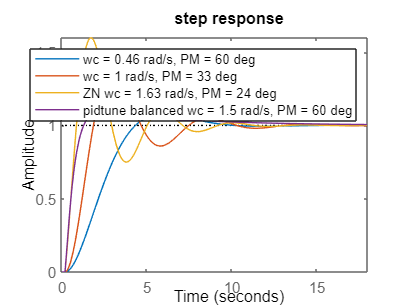

% MODIFY


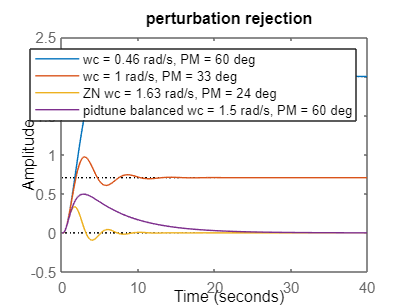

controller2 = pidtuneOptions('PhaseMargin',40)
[C5,info] = pidtune(G,'PID',wc,controller2)
T5 = feedback(G*C5,1);
P5 = feedback(G,C5);
bode(P5)


% 

By default the algorithm assume a 'balanced' design. It means that the algorithm try to optimize both reference tracking and perturbation rejection.

### 3.3 Compare DesignFocus

Instead of directly tuning the phase margin one can let the algorithm decide, just setting the DesignFocus parameter:

**Question 11**: compare the performance of the controllers with different DesignFocus parameters

% MODIFY

% 

Discussion here

## 4 More stuff

Look at stability margin on Nyquist plot (zoom near (-1,0)

set(gcf,'Visible','on');

controller1 =   pidtune with properties:

         PhaseMargin: 90
    NumUnstablePoles: 0
         DesignFocus: 'balanced'


nyquist(C5*G,C6*G,C7*G);

C4 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.768, Ki = 0.019, Kd = 1.74
 
Continuous-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.5000
           PhaseMargin: 90.0000


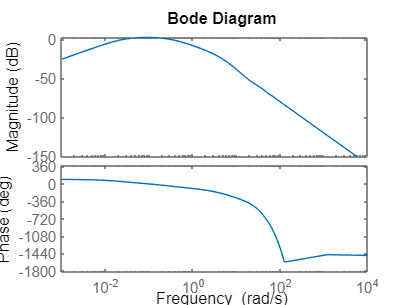

legend('reference-tracking',...
    'balanced',...
    'disturbance-rejection');

Discuss sensitivity function. The higher is the max of S the worse is the robustness

h = bodeplot(S5,S6,S7);

controller2 =   pidtune with properties:

         PhaseMargin: 40
    NumUnstablePoles: 0
         DesignFocus: 'balanced'


setoptions(h,'PhaseVisible','off');

C5 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.42, Ki = 0.304, Kd = 1.67
 
Continuous-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.5000
           PhaseMargin: 74.7286


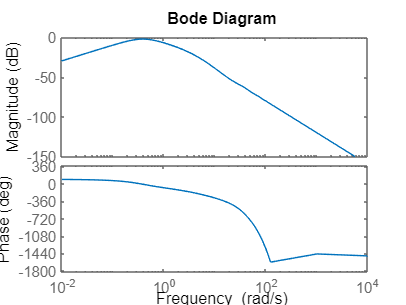

Unrecognized function or variable 'C6'.

legend('reference-tracking',...
    'balanced',...
    'disturbance-rejection');

Discuss low frequency gain (perturbation rejection) on T bode diagrams